% Auto-generated by cameraCalibrator app on 07-Mar-2019
%-------------------------------------------------------


% Define images to process
imageFileNames = {'C:\Users\bengo\Downloads\Photos\IMG_20190307_144835.jpg',...
    'C:\Users\bengo\Downloads\Photos\IMG_20190307_144839.jpg',...
    'C:\Users\bengo\Downloads\Photos\IMG_20190307_144845.jpg',...
    'C:\Users\bengo\Downloads\Photos\IMG_20190307_144849.jpg',...
    'C:\Users\bengo\Downloads\Photos\IMG_20190307_144902.jpg',...
    'C:\Users\bengo\Downloads\Photos\IMG_20190307_144907.jpg',...
    'C:\Users\bengo\Downloads\Photos\IMG_20190307_144912.jpg',...
    'C:\Users\bengo\Downloads\Photos\IMG_20190307_144916.jpg',...
    'C:\Users\bengo\Downloads\Photos\IMG_20190307_144925.jpg',...
    'C:\Users\bengo\Downloads\Photos\IMG_20190307_145956.jpg',...
    'C:\Users\bengo\Downloads\Photos\IMG_20190307_150000.jpg',...
    'C:\Users\bengo\Downloads\Photos\IMG_20190307_150007.jpg',...
    };
% Detect checkerboards in images
[imagePoints, boardSize, imagesUsed] = detectCheckerboardPoints(imageFileNames);

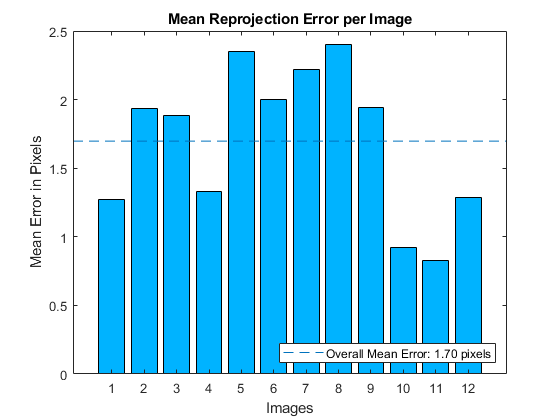

imageFileNames = imageFileNames(imagesUsed);

% Read the first image to obtain image size
originalImage = imread(imageFileNames{1});
[mrows, ncols, ~] = size(originalImage);

% Generate world coordinates of the corners of the squares
squareSize = 20;  % in units of 'millimeters'
worldPoints = generateCheckerboardPoints(boardSize, squareSize);

% Calibrate the camera
[cameraParams, imagesUsed, estimationErrors] = estimateCameraParameters(imagePoints, worldPoints, ...
    'EstimateSkew', false, 'EstimateTangentialDistortion', false, ...
    'NumRadialDistortionCoefficients', 2, 'WorldUnits', 'millimeters', ...
    'InitialIntrinsicMatrix', [], 'InitialRadialDistortion', [], ...
    'ImageSize', [mrows, ncols]);

% View reprojection errors
h1=figure; showReprojectionErrors(cameraParams);

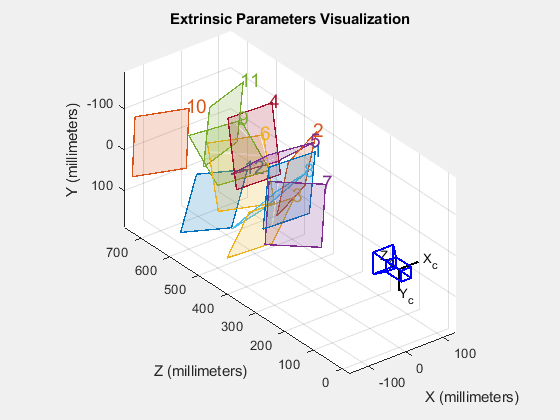


% Visualize pattern locations
h2=figure; showExtrinsics(cameraParams, 'CameraCentric');


% Display parameter estimation errors
displayErrors(estimationErrors, cameraParams);


			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Focal length (pixels):   [ 3070.0706 +/- 10.4694    3078.4402 +/- 10.4414 ]
Principal point (pixels):[ 1542.1939 +/- 6.5626     2051.4664 +/- 6.1459  ]
Radial distortion:       [    0.0890 +/- 0.0102       -0.3901 +/- 0.0461  ]

Extrinsics
----------
Rotation vectors:
                         [    0.1223 +/- 0.0035       -0.0559 +/- 0.0036        1.5805 +/- 0.0004  ]
                         [   -0.1031 +/- 0.0023       -0.5263 +/- 0.0025        1.4621 +/- 0.0008  ]
                         [    0.3839 +/- 0.0023       -0.3428 +/- 0.0021        1.5736 +/- 0.0009  ]
                         [   -0.2134 +/- 0.0024        0.1700 +/- 0.0030        1.6076 +/- 0.0006  ]
                         [    0.7373 +/- 0.0029       -0.6411 +/- 0.0029        1.5172 +/- 0.0010  ]
                         [    0.3568 +/- 0.0023        0.5964 +/- 0.0021        1.4123 +/- 0.0009  ]
 


% For example, you can use the calibration data to remove effects of lens distortion.
undistortedImage = undistortImage(originalImage, cameraParams);

% See additional examples of how to use the calibration data.  At the prompt type:
% showdemo('MeasuringPlanarObjectsExample')
% showdemo('StructureFromMotionExample')

%Intrinsic parameters
cameraParams.IntrinsicMatrix

ans =            3070.0706430238                         0                         0
                         0          3078.44016537562                         0
          1542.19387510416          2051.46635260177                         1



%Extrinsic parameters
cameraParams.RotationVectors .* cameraParams.TranslationVectors

ans =            6.6912742591676           5.7552602533178          572.935784781867
         -10.3039717135682          58.6141256641418          609.442186141381
          23.3344475143903         -16.2294675685102          695.878669496867
         -4.75164998150373         -31.3773224739326          756.835113550979
           34.443576158058          83.6915060910615          543.271457099125
          -5.5867682949675         -76.3917407238256          637.519339099098
          24.4039172698305          -23.936351073964          478.195226238324
          29.3908684715517          3.78273015153966          744.353334520456
         -42.9740657691582         -78.4664563805625          477.043621208733
         -9.98804933656441         -14.8427725910851          1061.54503980268



%World Points
cameraParams.WorldPoints

ans =      0     0
     0    20
     0    40
     0    60
     0    80
     0   100
     0   120
    20     0
    20    20
    20    40



%Pixel coordinates = intrinsic * extrinsic * world points 

